## Data Preparation

% Extracting data for each sample
sample_data = zeros(26, 176);  % Placeholder for sample data
std_avg = zeros(26, 176);       % Placeholder for average standard deviations
conc_avg = zeros(26, 3);        % Placeholder for average concentrations
for i = 1:26
    start_index = 5 * (i - 1) + 1;
    end_index = start_index + 4;
    sample_data(i, :) = DATA(start_index, :);
    std_avg(i, :) = mean(stdDATA(start_index:end_index, :), 1) / sqrt(5);
    conc_avg(i, :) = mean(CONC(start_index:end_index, :), 1);
end
disp('The sample data is: ');

The sample data is: 


disp(sample_data);

    0.1302    0.3089    0.1039    0.1189    0.0578   -0.0478    0.1588   -0.0006    0.1620    0.0463    0.2858   -0.0005    0.3644    0.0005    0.0805   -0.0167    0.2128    0.1214   -0.0036   -0.0440    0.1736    0.0748    0.0611    0.0713    0.0430    0.0358    0.0011    0.0389    0.0286    0.0312    0.0708    0.0229    0.0450    0.0581    0.0467    0.0518    0.0668    0.0845    0.0824    0.0887    0.0994    0.1001    0.1101    0.1145    0.1144    0.1220    0.1264    0.1270    0.1276    0.1257    0.1274    0.1248    0.1212    0.1192    0.1153    0.1112    0.1076    0.1031    0.0969    0.0925    0.0868    0.0826    0.0781    0.0726    0.0687    0.0650    0.0612    0.0576    0.0551    0.0526    0.0501    0.0487    0.0471    0.0460    0.0450    0.0444    0.0443    0.0435    0.0431    0.0427    0.0421    0.0413    0.0409    0.0403    0.0398    0.0398    0.0396    0.0394    0.0397    0.0397    0.0398    0.0400    0.0405    0.0411    0.0415    0.0424    0.0431    0.0445    0.0454    0.0464

disp('Average concentration data is: ');

Average concentration data is: 


disp(conc_avg);

    0.0031    0.0157    0.0069
    0.0031    0.0157    0.0206
    0.0031    0.0157    0.0344
    0.0031    0.0471    0.0069
    0.0031    0.0471    0.0206
    0.0031    0.0471    0.0344
    0.0031    0.0786    0.0069
    0.0031    0.0786    0.0206
    0.0031    0.0786    0.0344
    0.0092    0.0157    0.0069
    0.0092    0.0157    0.0206
    0.0092    0.0157    0.0344
    0.0092    0.0471    0.0069
    0.0092    0.0471    0.0206
    0.0092    0.0471    0.0344
    0.0092    0.0786    0.0069
    0.0092    0.0786    0.0206
    0.0092    0.0786    0.0344
    0.0153    0.0157    0.0069
    0.0153    0.0157    0.0206
    0.0153    0.0157    0.0344
    0.0153    0.0471    0.0069
    0.0153    0.0471    0.0206
    0.0153    0.0471    0.0344
    0.0153    0.0786    0.0069
    0.0153    0.0786    0.0344



## Part A: Visualization and Multilinear Regression

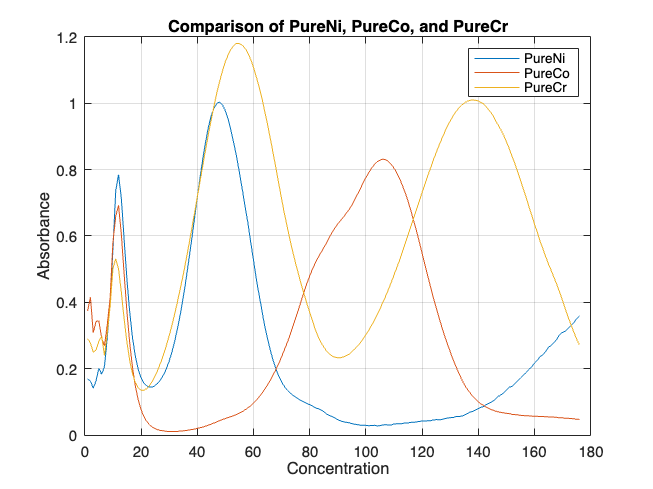

% Visualization
figure();
set(gcf, 'Name', 'Comparison of PureNi, PureCo, and PureCr');
plot(PureNi);
hold on;
plot(PureCo);
plot(PureCr);
hold off;
legend('PureNi', 'PureCo', 'PureCr');
xlabel('Concentration');
ylabel('Absorbance');
title('Comparison of PureNi, PureCo, and PureCr');
grid on;

% Index and data for multilinear regression
[maxValue_Ni, maxIndex_Ni] = max(PureNi);
[maxValue_Cr, maxIndex_Cr] = max(PureCr);
[maxValue_Co, maxIndex_Co] = max(PureCo);
Y_sample_MLR = [sample_data(:, maxIndex_Ni), sample_data(:, maxIndex_Cr), sample_data(:, maxIndex_Co)];
% Multilinear regression
B_sample_MLR = inv(Y_sample_MLR' * Y_sample_MLR) * Y_sample_MLR' * conc_avg;
RMSE_sample_MLR = norm(conc_avg - Y_sample_MLR * B_sample_MLR);
% RMSE by Leave-One-Out Cross-Validation for OLS
RMSE_LOOCV_OLS = LOOCV_OLS(Y_sample_MLR, conc_avg);
disp('RMSE by LOOCV for OLS: ');

RMSE by LOOCV for OLS: 


disp(RMSE_LOOCV_OLS);

    0.0007    0.0453    0.0171



## Part B: Partial Least Squares Regression (PLSR)

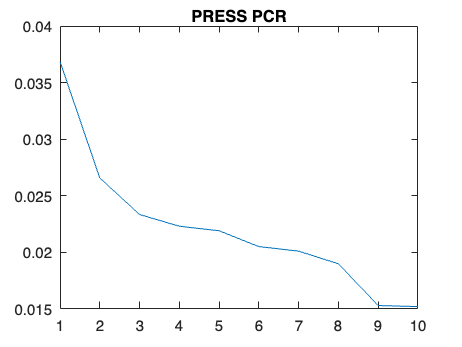

num_PCs = 10;
RMSE_PCR = zeros(num_PCs, 3);
for i = 1:num_PCs
    RMSE_PCR(i, :) = LOOCV_PCR(sample_data, conc_avg, i);
end
PRESS_PCR = sum(RMSE_PCR, 2);
figure();
set(gcf, 'Name', 'PRESS PCR');
plot(PRESS_PCR);
title('PRESS PCR');

disp('RMSE by LOOCV for PCR: ');

RMSE by LOOCV for PCR: 


disp(RMSE_PCR);

    0.0037    0.0212    0.0119
    0.0037    0.0143    0.0086
    0.0030    0.0126    0.0078
    0.0029    0.0118    0.0076
    0.0028    0.0114    0.0077
    0.0026    0.0107    0.0072
    0.0025    0.0103    0.0072
    0.0024    0.0099    0.0067
    0.0019    0.0081    0.0053
    0.0018    0.0081    0.0053



disp('PRESS by LOOCV for PCR: ');

PRESS by LOOCV for PCR: 


disp(PRESS_PCR);

    0.0369
    0.0266
    0.0233
    0.0223
    0.0219
    0.0205
    0.0201
    0.0190
    0.0153
    0.0152



## Part C: Scaled PLSR (SPCR)

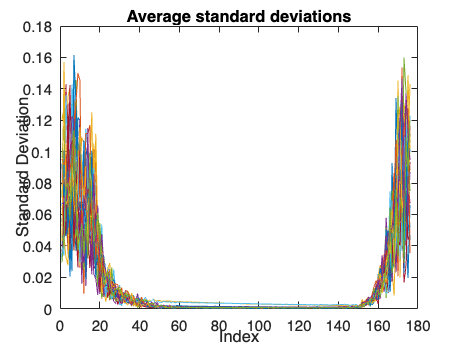

figure();
set(gcf, 'Name', 'Average standard deviations');
plot(std_avg');
title('Average standard deviations');
ylabel('Standard Deviation');
xlabel('Index');

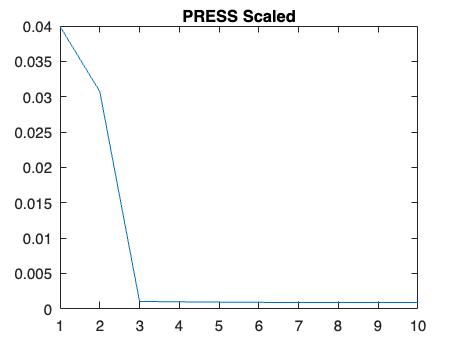

stds = mean(std_avg);  % Assuming variation only along wavelength not mixture
L = diag(stds);
Y_scaled = sample_data * inv(L);  % Scaling
RMSE_SPCR = zeros(num_PCs, 3);
for i = 1:num_PCs
    RMSE_SPCR(i, :) = LOOCV_PCR(Y_scaled, conc_avg, i);
end
PRESS_Scaled = sum(RMSE_SPCR, 2);
figure();
set(gcf, 'Name', 'PRESS Scaled');
plot(PRESS_Scaled);
title('PRESS Scaled');

disp('RMSE by LOOCV for SPCR: ');

RMSE by LOOCV for SPCR: 


disp(RMSE_SPCR);

    0.0031    0.0260    0.0108
    0.0033    0.0212    0.0063
    0.0001    0.0005    0.0004
    0.0001    0.0005    0.0004
    0.0001    0.0005    0.0004
    0.0001    0.0005    0.0003
    0.0001    0.0004    0.0003
    0.0001    0.0004    0.0003
    0.0001    0.0005    0.0003
    0.0001    0.0005    0.0003



disp('PRESS by LOOCV for SPCR: ');

PRESS by LOOCV for SPCR: 


disp(PRESS_Scaled);

    0.0400
    0.0307
    0.0010
    0.0010
    0.0009
    0.0009
    0.0009
    0.0009
    0.0009
    0.0009



## Part D: MLPCA

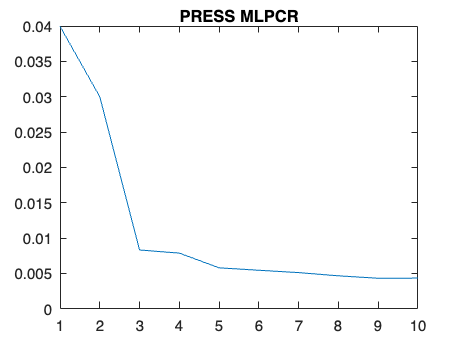

RMSE_MLPCR = zeros(num_PCs, 3);
for nPC = 1:num_PCs
    RMSE_MLPCR(nPC, :) = LOOCV_MLPCR(sample_data, conc_avg, std_avg, nPC);
end
PRESS_MLPCR = sum(RMSE_MLPCR, 2);
figure();
set(gcf, 'Name', 'PRESS MLPCR');
plot(PRESS_MLPCR);
title('PRESS MLPCR');

disp('RMSE by LOOCV for MLPCR: ');

RMSE by LOOCV for MLPCR: 


disp(RMSE_MLPCR);

    0.0033    0.0252    0.0114
    0.0032    0.0182    0.0086
    0.0004    0.0069    0.0010
    0.0004    0.0064    0.0011
    0.0004    0.0044    0.0011
    0.0004    0.0041    0.0010
    0.0004    0.0038    0.0009
    0.0003    0.0034    0.0009
    0.0003    0.0031    0.0008
    0.0003    0.0032    0.0008



disp('PRESS by LOOCV for MLPCR: ');

PRESS by LOOCV for MLPCR: 


disp(PRESS_MLPCR);

    0.0400
    0.0300
    0.0083
    0.0079
    0.0058
    0.0054
    0.0051
    0.0047
    0.0043
    0.0043

